# **Callibration Curve ISIM Lab 2**

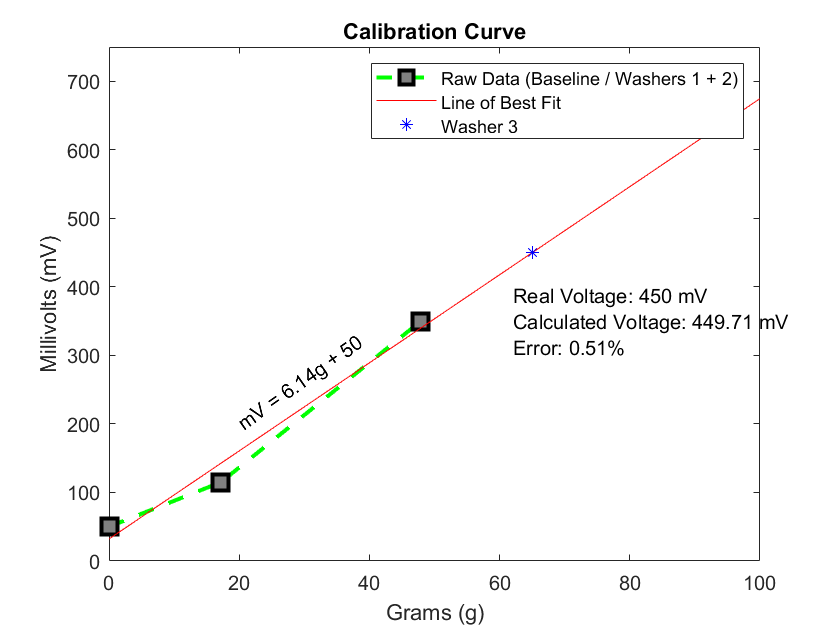

% Clear Graph
clf;

% Raw Data Plot
x = [0, 17.2, 47.9];
y = [50, 115, 350];

plot(x,y,'--gs',...
    'LineWidth',2,...
    'MarkerSize',10,...
    'MarkerEdgeColor','k',...
    'MarkerFaceColor',[0.5,0.5,0.5])

hold on;

% Washer 3 Plot
washer_3_x = 17.2 + 47.9;
washer_3_y = 450;

% Best Fit Plot

x_best_fit = [0, 17.2, 47.9, 17.2 + 47.9, 100];
y_best_fit = [50, 115, 350, 450, 675];

p = polyfit(x_best_fit,y_best_fit,1);
f = polyval(p,x_best_fit);

hold on

washer_3_data = {'Real Voltage: 450 mV', 'Calculated Voltage: 449.71 mV', 'Error: 0.51%'};
text(washer_3_x-3,washer_3_y - 100,washer_3_data)

plot(x_best_fit,f,'r-');

txt = ['mV = 6.14g + 50'];
h = text(20,200,txt);
set(h,'Rotation',35);

plot(washer_3_x,washer_3_y,'b*')

xlim([0 100])
ylim([0 750])

title("Calibration Curve")
legend("Raw Data (Baseline / Washers 1 + 2)", "Line of Best Fit", "Washer 3")
xlabel('Grams (g)') 
ylabel('Millivolts (mV)') 